# Predict classification based on pre-trained models

In this exercise, you will apply a pre-trained text classification model to categorize a product based on its ingredients. The ingredients text, extracted in Exercise 1, will be processed and analyzed using a bag-of-words approach. This exercise demonstrates the application of machine learning techniques to real-world text data, providing insights into how products can be automatically categorized based on their textual descriptions.

### **Task 1: Load the data for prediction**

Description:

- This task involves loading the necessary data and models for prediction. The `bagOfWords` model and the `simpleTextClassifierMdl` are pre-trained and stored in `prediction_data.mat`.

- The extracted text from the product's image, saved in `new_product_ingredients.mat`, is also loaded.

Expected Results:

- The workspace will contain the `bagOfWords` model, the `simpleTextClassifierMdl`, and the `extractedText`. These will be used in subsequent tasks to preprocess the text and predict the product category.

% To regenerate the pretrained models
% filename = 'products_data.csv';
% data = readtable(filename,'TextType','string');
%  [bagOfWords, simpleTextClassifierMdl] = trainSimpleTextClassifier(data);

load("prediction_data.mat","bagOfWords","simpleTextClassifierMdl");

load("new_product_ingredients.mat", "extractedText")

### **Task 2: Pre-process Text Data**

Description:

- This task involves preprocessing the extracted text to prepare it for classification. The text is tokenized, stop words are removed, words are lemmatized, and punctuation is erased.

- The `preprocessText` function encapsulates these preprocessing steps, ensuring the text is in a suitable format for the bag-of-words model.

Expected Results:

- The variable `documentsNew` will contain the preprocessed version of the extracted text, ready for encoding with the bag-of-words model.

documentsNew = preprocessText(extractedText)

documentsNew =   tokenizedDocument:

   72 tokens: ingredients ingredient agua glycerin caprylic capric triglyceride glyceryl oleate citrate squalane aloe barbadensis camellia japonica srhydrozoan polypeptide1 vegan collagen ahnfeltiopsis concinna chamomilla recutita matricaria citrus aurantium dulcis orange jasminum officinale jasmine leuconostoc radish root ferment filtrate arnica montana hydrolyze jojoba ester sodium hyaluronate lecithin pullulan hydrogenate lecithin silica caprylyl capryl glucoside xanthan gum sclerotium gum cetearyl alcohol maltodextrin glucose citric potassium sorbate ethylhexylglycerin sodium benzoate phenoxyethanol amyl cinnamal linalool parfum natural naturelle


### **Task 3: Predict Category for the Product**

Description:

- This task involves encoding the preprocessed text (`documentsNew`) using the `bagOfWords` model, transforming it into a numeric format suitable for the classifier.

- The `simpleTextClassifierMdl` is then used to predict the category of the product based on the encoded text.

Expected Results:

- The variable `labelsNew` will contain the predicted category label(s) for the product. This output represents the model's classification decision based on the product's ingredients.

XNew = encode(bagOfWords,documentsNew);
labelsNew = predict(simpleTextClassifierMdl, XNew)

labelsNew = 1×1 cell array
    {'toxic'}


### Task 4: Calculate the classification accuracy

Description:

- This task involves evaluating the performance of the classifier using a predefined testing function, `testClassifierModel`.

- The function predicts labels for a test dataset and calculates the classification accuracy, providing a quantitative measure of the model's performance.

Expected Results:

- The output will include the classification accuracy of the model printed to the console. This accuracy indicates how well the model generalizes to unseen data, reflecting its effectiveness in categorizing products based on their ingredients.

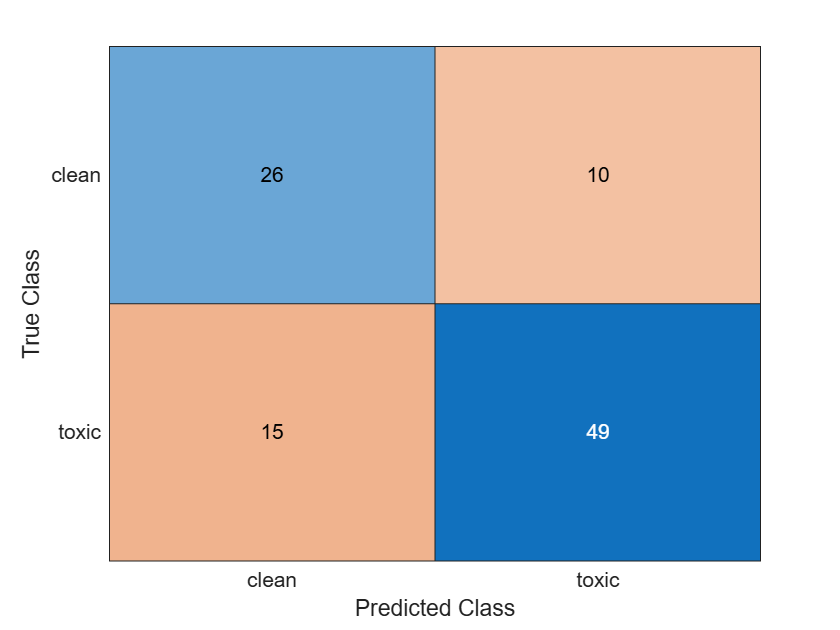

Classification accuracy is: 75%


testClassifierModel()